1번 문제

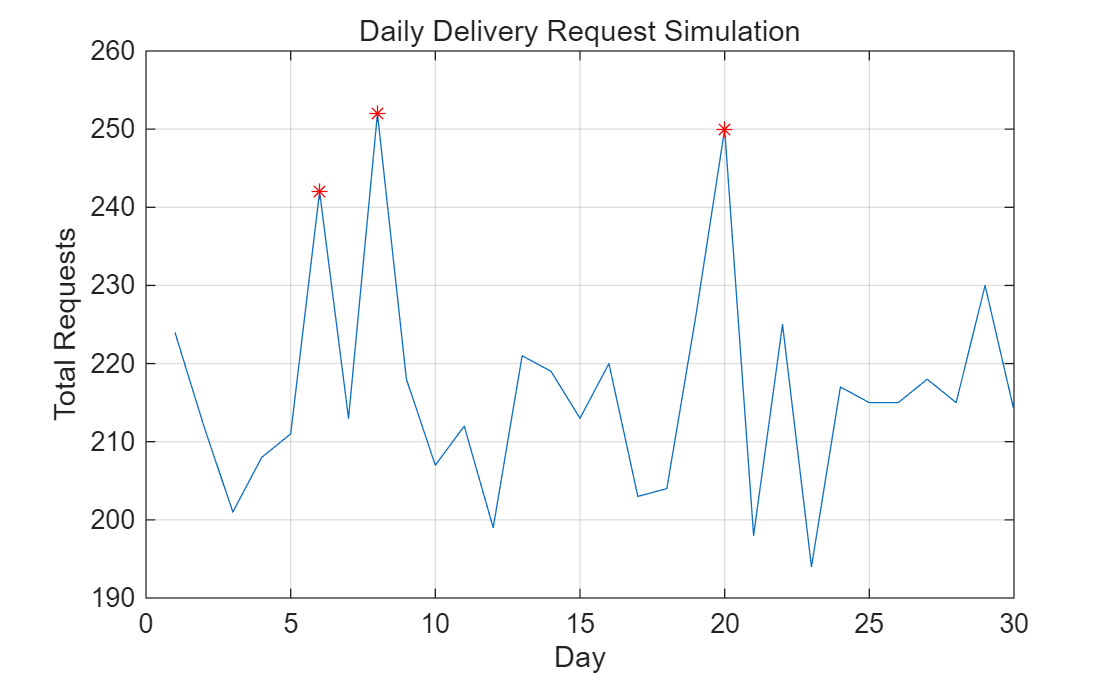

clear;
clc;

%a번 문제
rng(14);

%b번 문제
request=poissrnd(18,30,12);

%c번 문제
dailyTotal=sum(request,2);

%d번 문제
busyDay=dailyTotal>=240;

%e번 문제
numBusyDay=sum(busyDay);

%f번 문제
hourlyMean=mean(request,1);

%g번 문제
figure;
plot(1:30,dailyTotal);
hold on;
plot(find(busyDay),dailyTotal(busyDay),'r*');

%h번 문제
xlabel('Day');
ylabel('Total Requests');
title('Daily Delivery Request Simulation');
grid on;
hold off;

2번 문제

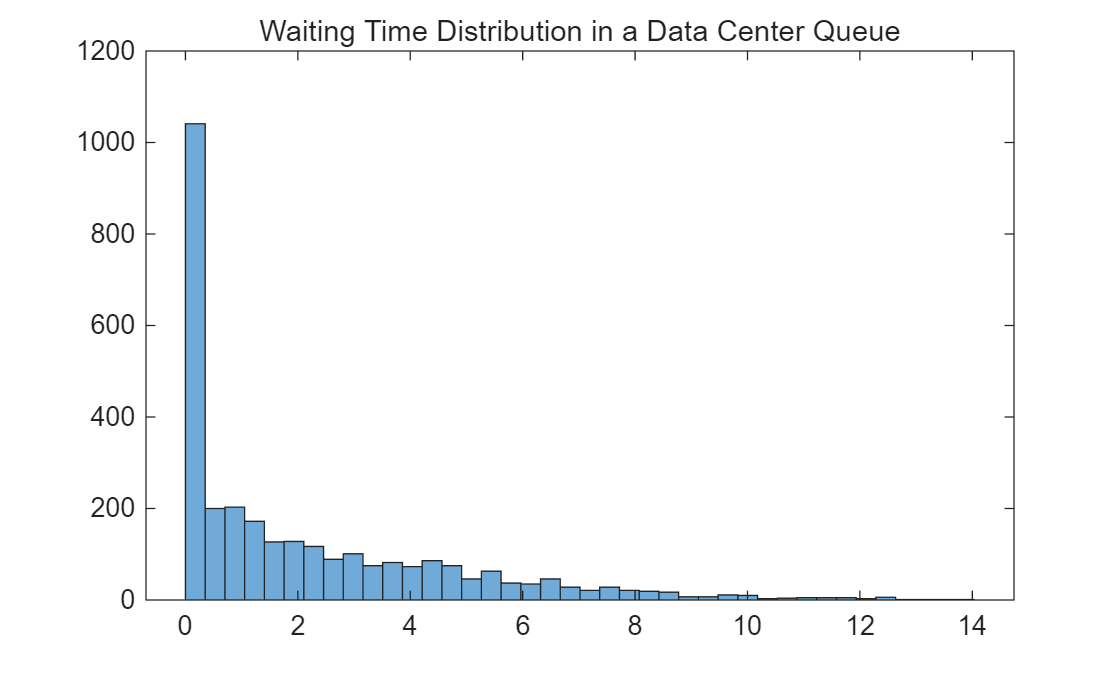

clear;
clc;

%a번 문제
n=3000;

%b번 문제
interArrival=exprnd(1.2,1,n);

%c번 문제
arrival=cumsum(interArrival);

%d번 문제
service=exprnd(0.9,1,n);

%e번 문제
startTime=zeros(1,n);
finishTime=zeros(1,n);
startTime(1)=arrival(1);
finishTime(1)=startTime(1)+service(1);

for i=2:n
    startTime(i)=max(arrival(i),finishTime(i-1));
    finishTime(i)=startTime(i)+service(i);
end

%f번 문제
waitingTime=startTime-arrival;

%g번 문제
meanWait=mean(waitingTime);
maxWait=max(waitingTime);
longWaitRatio=sum(waitingTime>=5)/n;

%h번 문제
figure;
histogram(waitingTime,40);

%i번 문제
title('Waiting Time Distribution in a Data Center Queue');

3번 문제

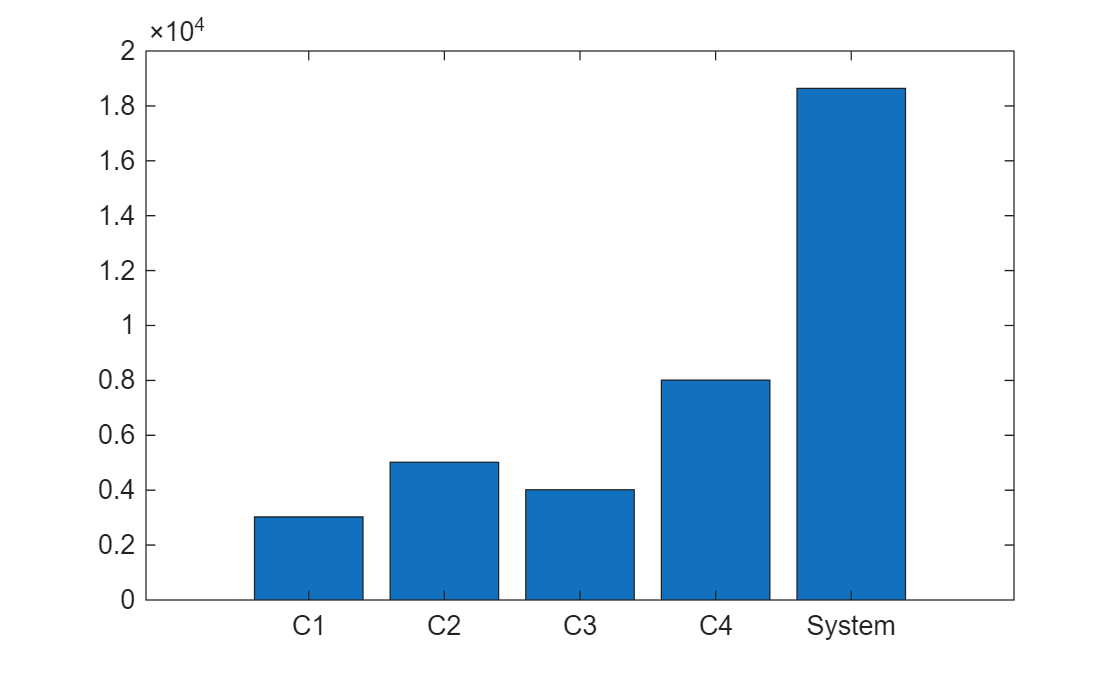

clear;
clc;

%a번 문제
n=100000;

%b번 문제
c1=rand(1,n)<0.97;
c2=rand(1,n)<0.95;
c3=rand(1,n)<0.96;
c4=rand(1,n)<0.92;

%c번 문제
systemWorking=c1&c2&c3&c4;

%d번 문제
reliabilityEst=sum(systemWorking)/n;

%e번 문제
reliabilityTrue=0.97*0.95*0.96*0.92;

%f번 문제
absError=abs(reliabilityEst-reliabilityTrue);

%g번 문제
failCounts=[sum(~c1),sum(~c2),sum(~c3),sum(~c4),sum(~systemWorking)];

%h번 문제
figure;
bar(failCounts);
xticklabels({'C1','C2','C3','C4','System'});

4번 문제

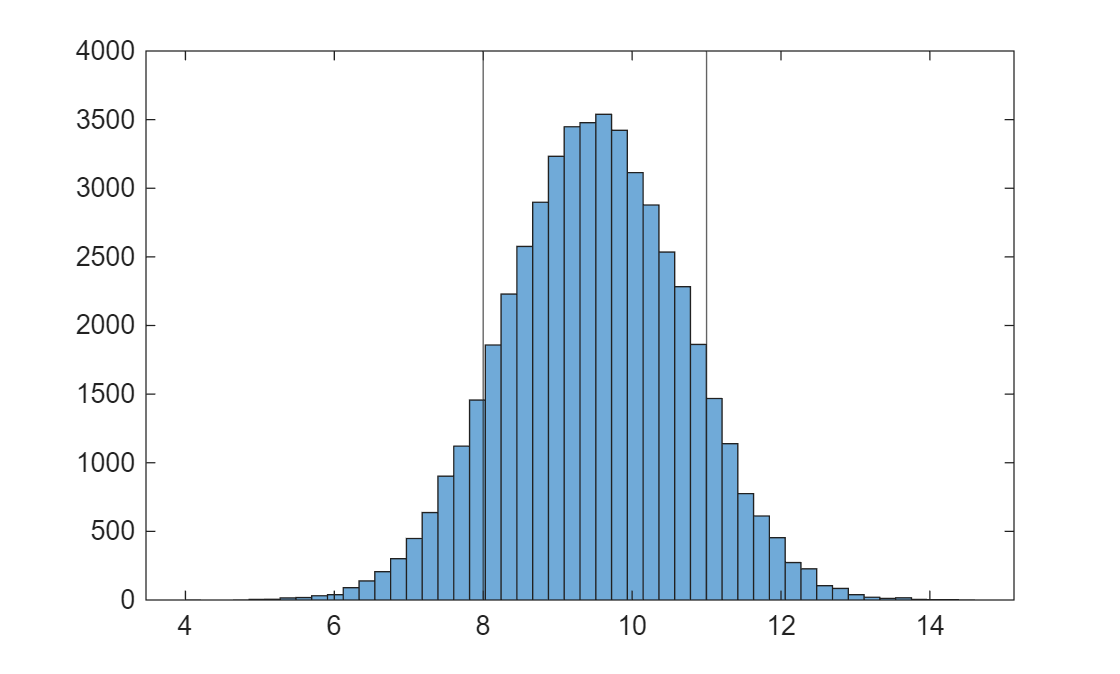

clear;
clc;

%a번 문제
batteryLife=normrnd(9.5,1.2,1,50000);

%b번 문제
lowBattery=batteryLife<8;

%c번 문제
normalBattery=batteryLife>=8 & batteryLife<11;

%d번 문제
excellentBattery=batteryLife>=11;

%e번 문제
gradeCounts=[sum(lowBattery),sum(normalBattery),sum(excellentBattery)];

%f번 문제
gradeRatio=gradeCounts/50000;

%g번 문제
figure;
histogram(batteryLife,50);
hold on;
xline(8);
xline(11);
hold off;

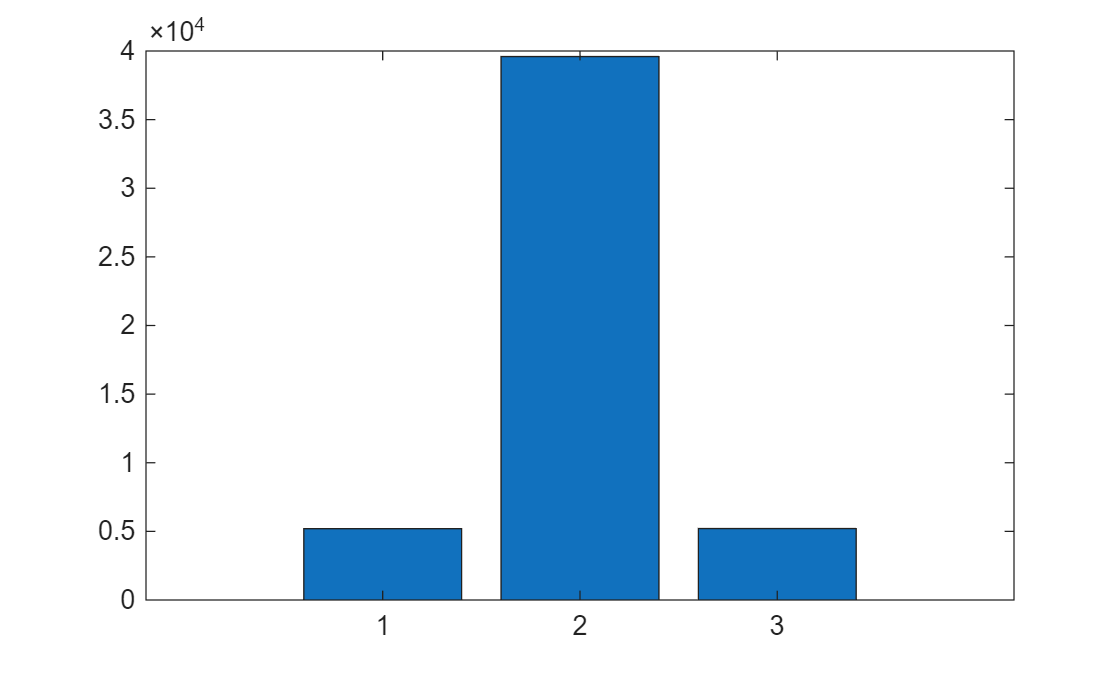


%h번 문제
figure;
bar(gradeCounts);

5번 문제

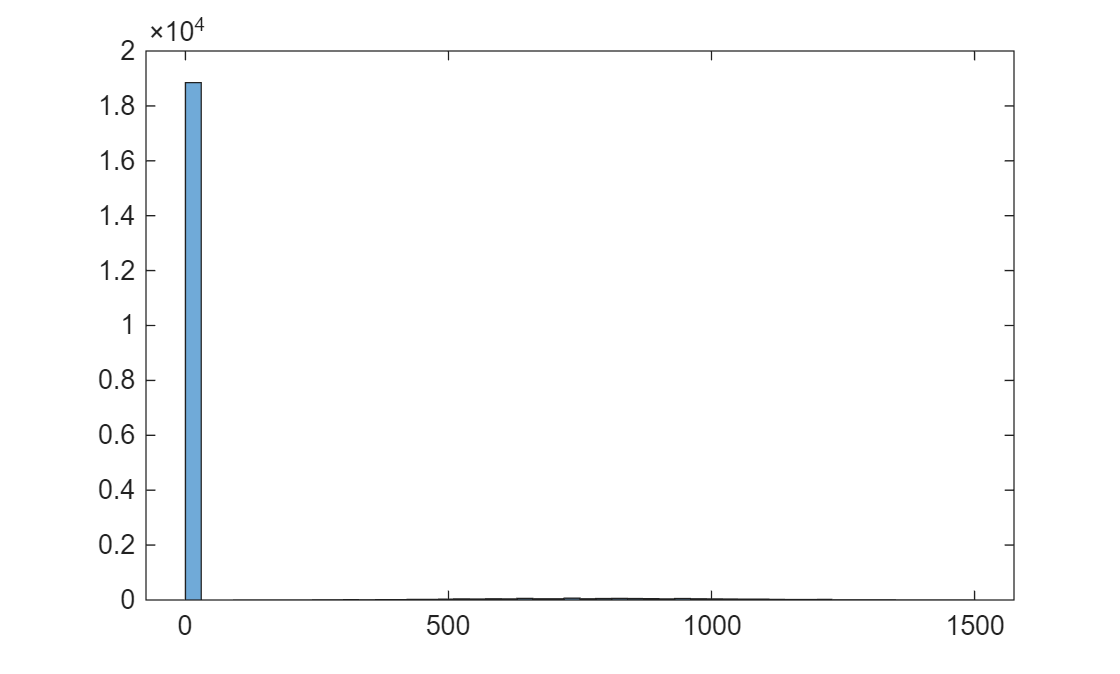

clear;
clc;

%a번 문제
n=20000;

%b번 문제
hasClaim=rand(1,n)<0.06;

%c번 문제
claimAmount=normrnd(800,250,1,n);

%d번 문제
claimAmount(claimAmount<0)=0;

%e번 문제
claimPayment=hasClaim.*claimAmount;

%f번 문제
totalPayment=sum(claimPayment);
meanPayment=mean(claimPayment);
meanClaimOnly=sum(claimPayment)/sum(hasClaim);

%g번 문제
numLargeClaim=sum(claimPayment>=1200);

%h번 문제
figure;
histogram(claimPayment);

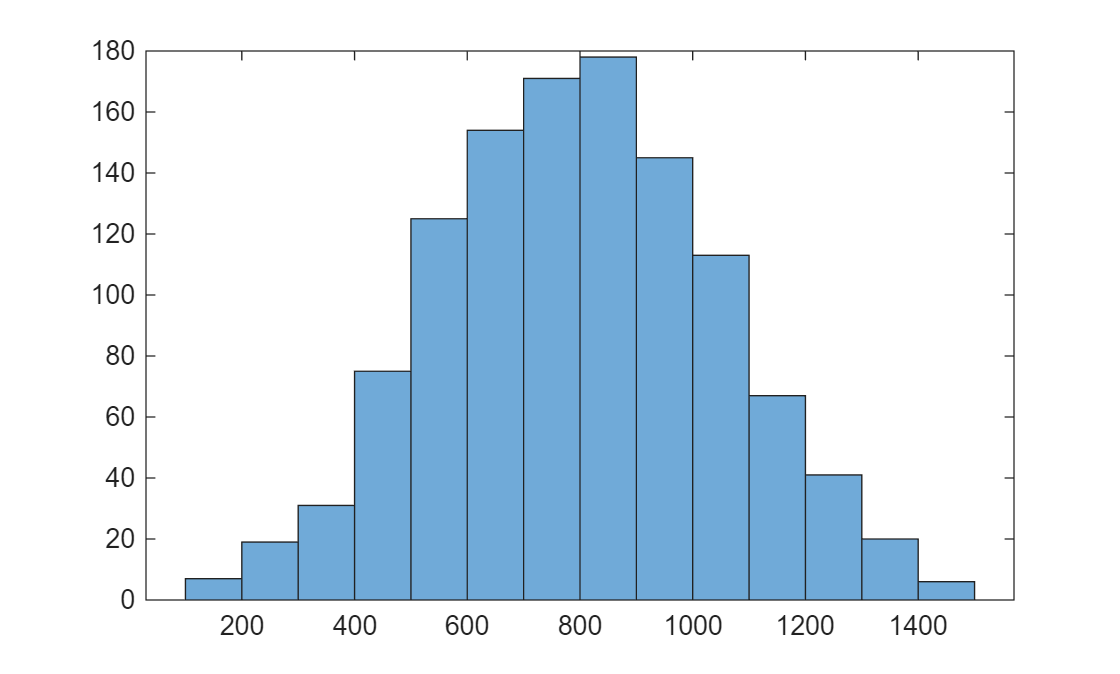


figure;
histogram(claimPayment(claimPayment>0));

6번 문제

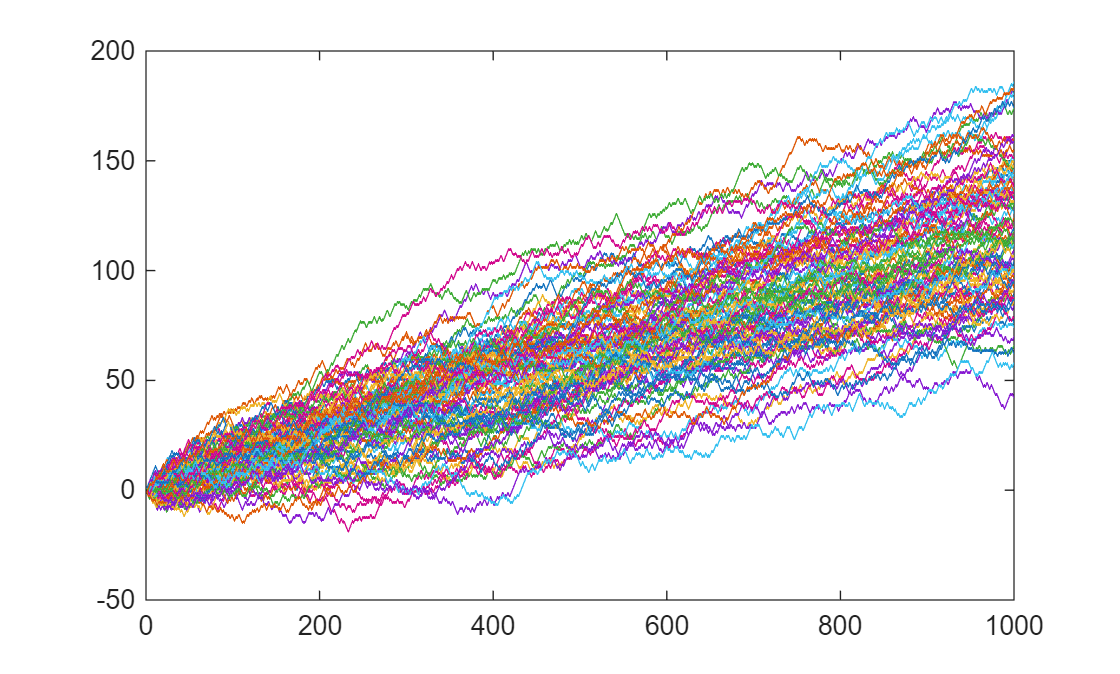

clear;
clc;

%a번 문제
n=1000;
m=100;

%b번 문제
steps=2*(rand(n,m)<0.56)-1;

%c번 문제
walks=cumsum(steps);

%d번 문제
figure;
plot(walks);

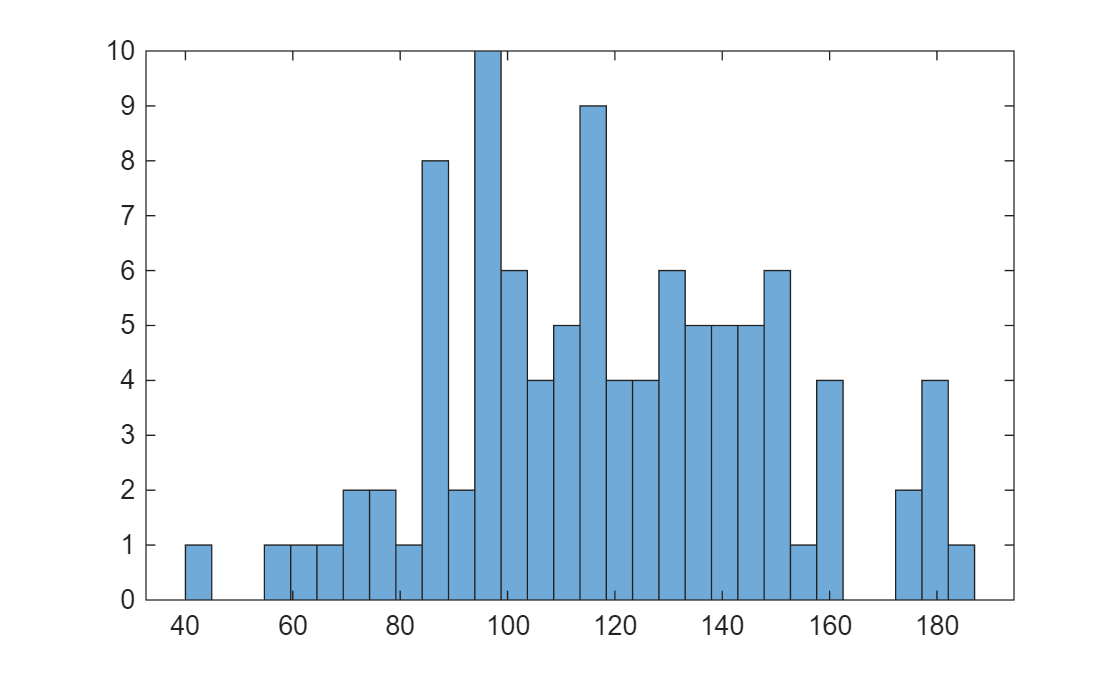


%e번 문제
finalPosition=walks(end,:);

%f번 문제
meanFinal=mean(finalPosition);
stdFinal=std(finalPosition);

%g번 문제
rightDriftRatio=sum(finalPosition>=100)/m;

%h번 문제
figure;
histogram(finalPosition,30);

7번 문제

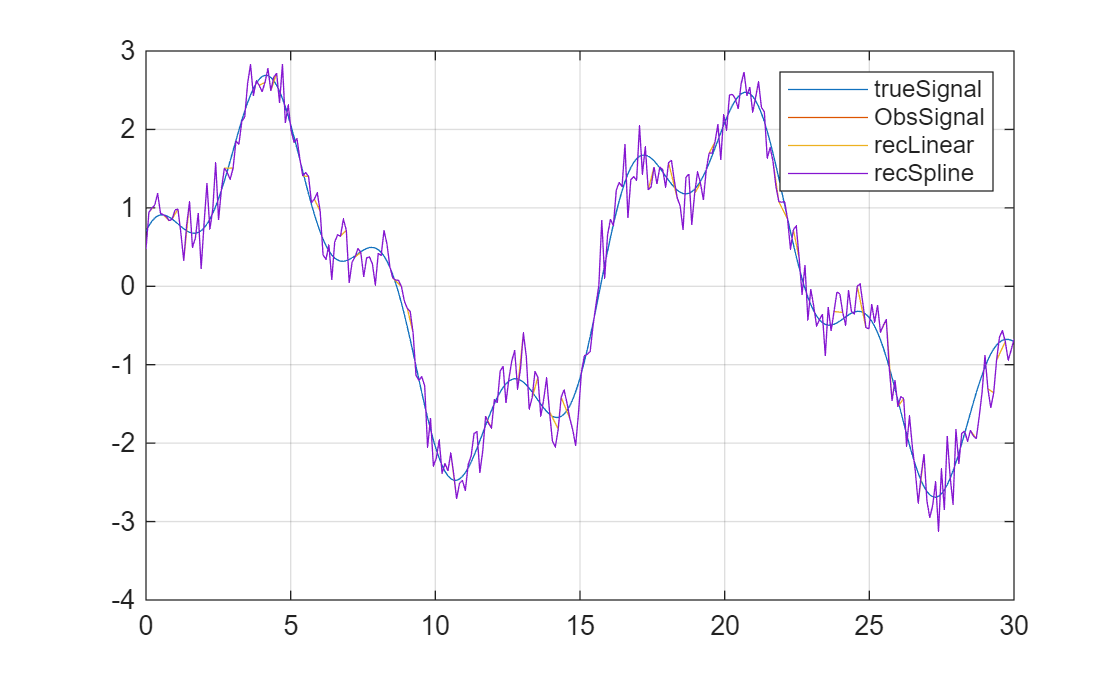

clear;
clc;

%a번 문제
rng(7);

%b번 문제
t=linspace(0,30,300);

%c번 문제
trueSignal=2*sin(0.4*t)+0.7*cos(1.5*t);

%d번 문제
obsSignal=trueSignal+0.25*randn(size(t));

%e번 문제
index=randperm(length(t),45);
obsSignal(index)=NaN;

%f번 문제
valid=~isnan(obsSignal);

%g번 문제
recLinear=interp1(t(valid),obsSignal(valid),t,'linear');

%h번 문제
recSpline=interp1(t(valid),obsSignal(valid),t,'spline');

%i번 문제
rmseLinear=sqrt(mean((trueSignal-recLinear).^2));
rmseSpline=sqrt(mean((trueSignal-recSpline).^2));

%j번 문제
figure;
plot(t,trueSignal);
hold on;
plot(t,obsSignal);
plot(t,recLinear);
plot(t,recSpline);
legend('trueSignal','ObsSignal','recLinear','recSpline');
grid on;
hold off;

8번 문제

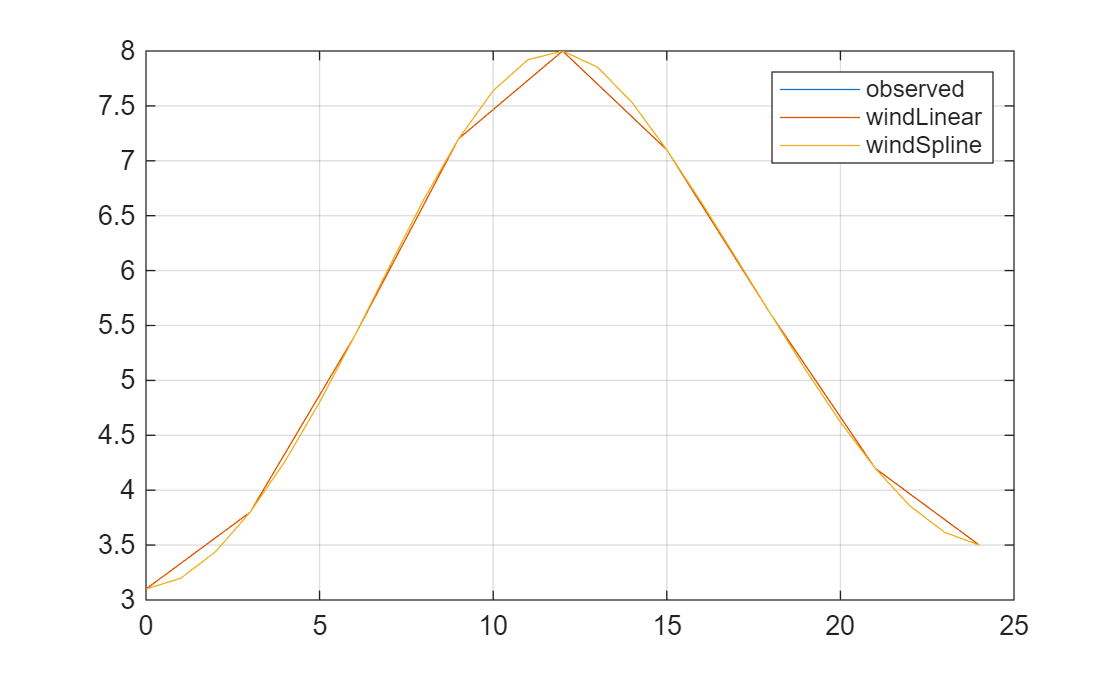

clear;
clc;

%a번 문제
timeObs=[0 3 6 9 12 15 18 21 24];
windObs=[3.1 3.8 5.4 7.2 8.0 7.1 5.6 4.2 3.5];

%b번 문제
timeHourly=0:24;

%c번 문제
windLinear=interp1(timeObs,windObs,timeHourly,'linear');

%d번 문제
windSpline=interp1(timeObs,windObs,timeHourly,'spline');

%e번 문제
diffWind=windSpline-windLinear;

%f번 문제
maxDiff=max(abs(diffWind));

%g번 문제
figure;
plot(timeObs,windObs);
hold on;
plot(timeHourly,windLinear);
plot(timeHourly,windSpline);
legend('observed','windLinear','windSpline');
grid on;
hold off;

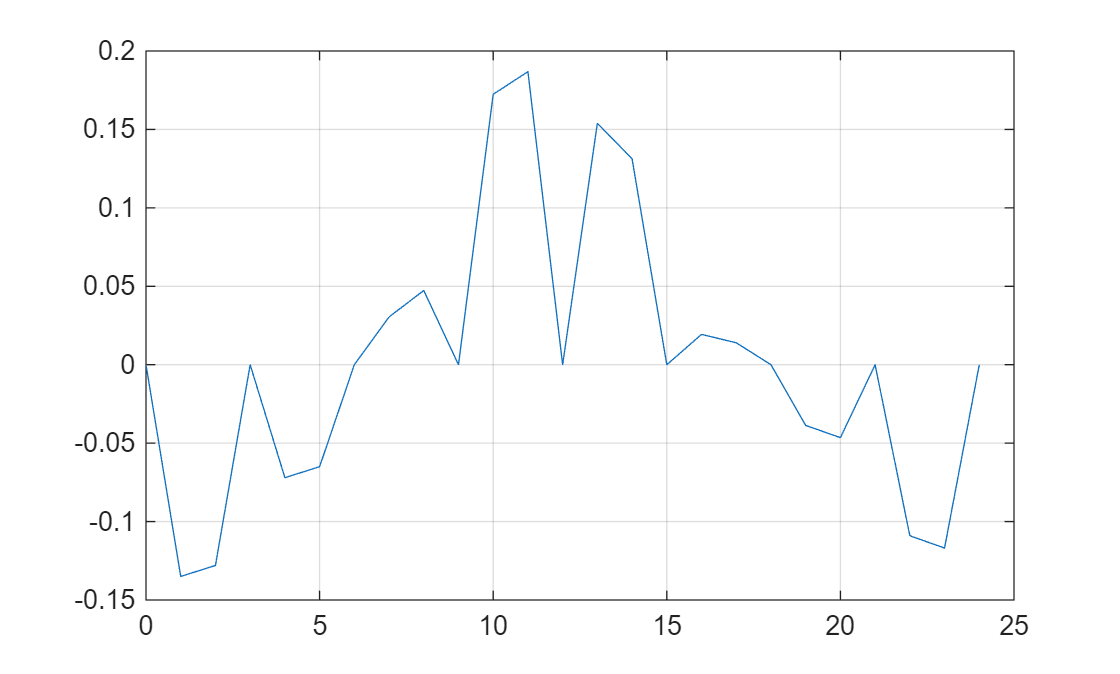


%h번 문제
figure;
plot(timeHourly,diffWind);
grid on;

9번 문제

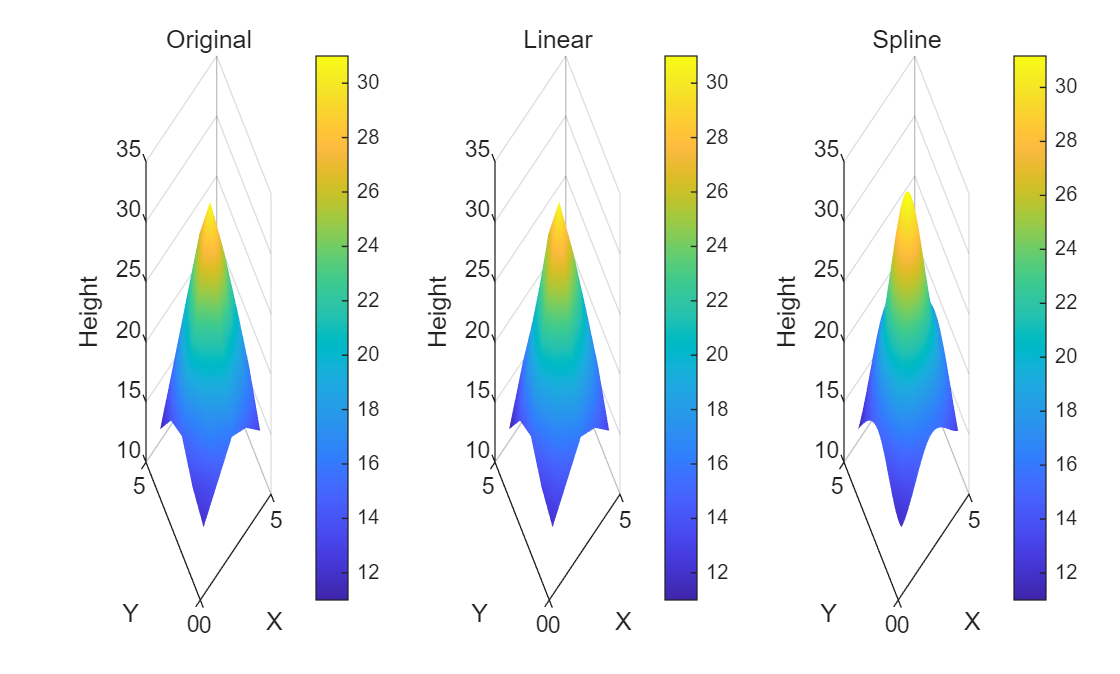

clear;
clc;

%a번 문제
[X,Y]=meshgrid(1:5,1:5);

%b번 문제
H=[12 14 16 15 13;13 18 22 20 16;15 23 31 25 18;14 20 26 24 17;11 15 18 16 14];

%c번 문제
[Xq,Yq]=meshgrid(1:0.1:5,1:0.1:5);

%d번 문제
HqLinear=interp2(X,Y,H,Xq,Yq,'linear');

%e번 문제
HqSpline=interp2(X,Y,H,Xq,Yq,'spline');

%f번 문제 g번 문제
figure;
tiledlayout(1,3);
nexttile;
surf(X,Y,H);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Original');

nexttile;
surf(Xq,Yq,HqLinear);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Linear');

nexttile;
surf(Xq,Yq,HqSpline);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Spline');

10번 문제

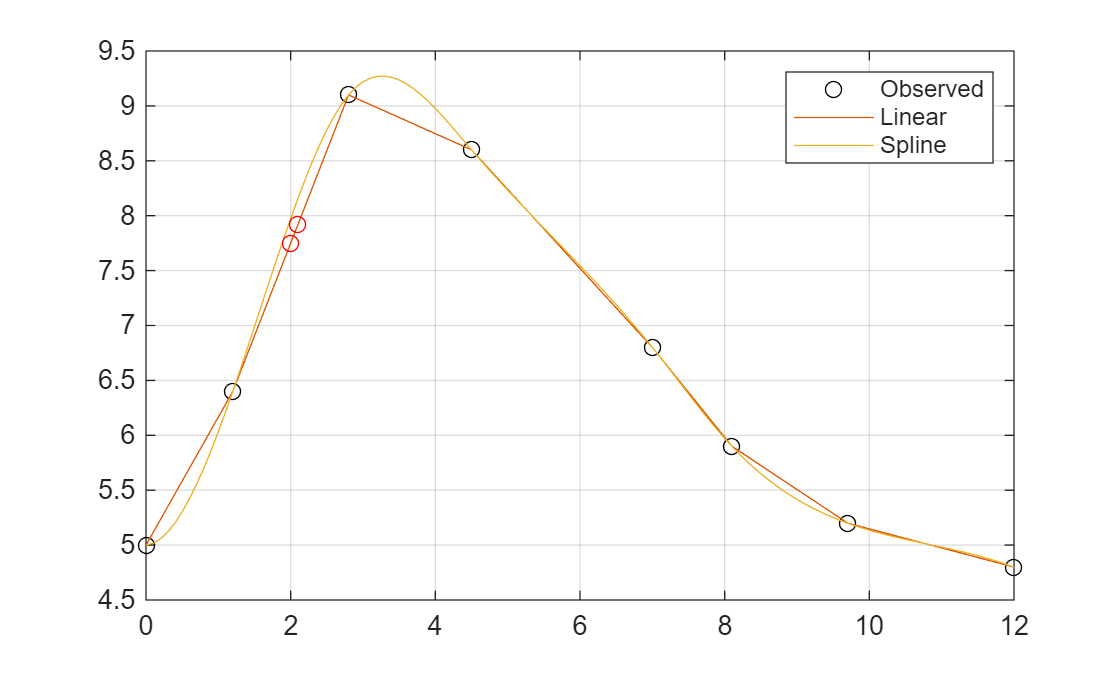

clear;
clc;

%a번 문제
tObs=[0 1.2 2.8 4.5 7.0 8.1 9.7 12.0];
cObs=[5.0 6.4 9.1 8.6 6.8 5.9 5.2 4.8];

%b번 문제
tq=0:0.1:12;

%c번 문제
cqLinear=interp1(tObs,cObs,tq,'linear');

%d번 문제
cqSpline=interp1(tObs,cObs,tq,'spline');

%e번 문제
deltaC=diff(cqLinear);

%f번 문제
[~,idxMaxChange]=max(abs(deltaC));

%g번 문제
changeInterval=[tq(idxMaxChange),tq(idxMaxChange+1)];

%h번 문제
figure;
plot(tObs,cObs,'ok');
hold on;
plot(tq,cqLinear);
plot(tq,cqSpline);
plot(tq([idxMaxChange idxMaxChange+1]),cqLinear([idxMaxChange idxMaxChange+1]),'ro');
legend('Observed','Linear','Spline');
grid on;
hold off;

11번 문제

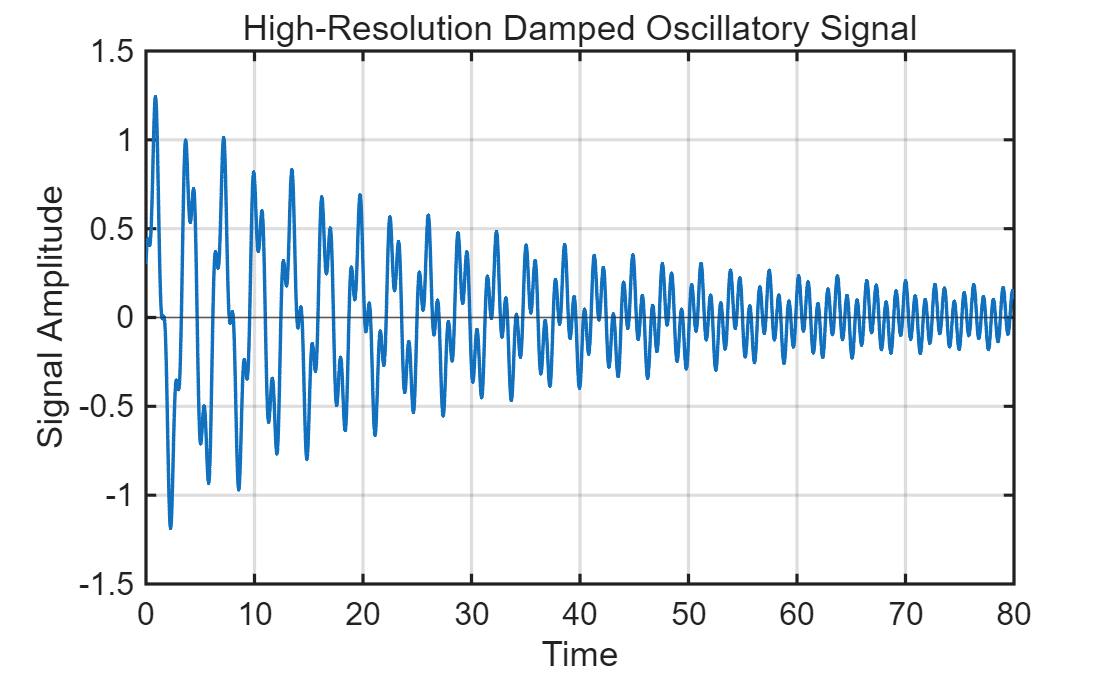

clear;
clc;

%a번 문제
t=linspace(0,80,12000);

%b번 문제
y=exp(-0.04*t).*sin(2*t)+0.3*exp(-0.01*t).*cos(7*t);

%c번 문제
figure('Color','w');

%d번 문제
plot(t,y,'LineWidth',1.3);

%e번 문제
yline(0);

%f번 문제
xlabel('Time');
ylabel('Signal Amplitude');
title('High-Resolution Damped Oscillatory Signal');

%g번 문제
xlim([0 80]);
grid on;
box on;

%h번 문제
set(gca,'FontSize',12,'LineWidth',1.2);

%i번 문제
print('damped_signal.png','-dpng','-r300');

12번 문제

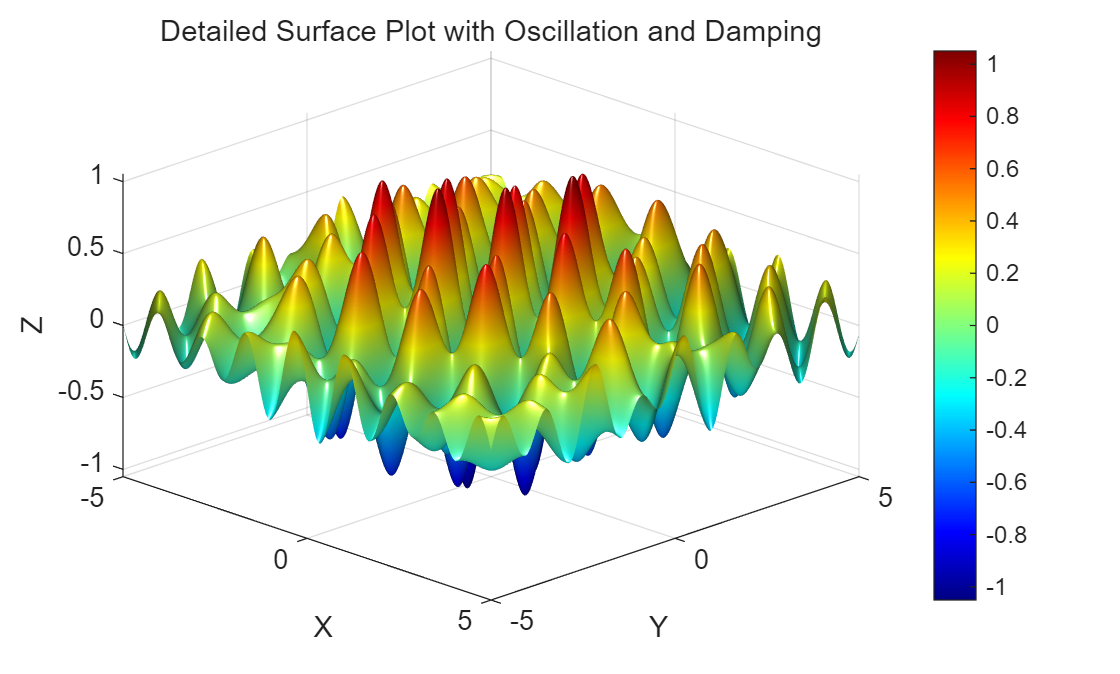

clear;
clc;

%a번 문제
x=linspace(-5,5,600);
y=linspace(-5,5,600);

%b번 문제
[X,Y]=meshgrid(x,y);

%c번 문제
Z=exp(-0.06*(X.^2+Y.^2)).*sin(4*X).*cos(3*Y)+0.2*sin(X.*Y);

%d번 문제
figure;
surf(X,Y,Z);

%e번 문제
shading interp;
colormap(jet);
colorbar;

%f번 문제
xlabel('X');
ylabel('Y');
zlabel('Z');

%g번 문제
title('Detailed Surface Plot with Oscillation and Damping');

%h번 문제
view(45,30);
camlight headlight;
lighting phong;


%i번 문제
maxZ=max(Z(:));
minZ=min(Z(:));

%j번 문제
[rowMax,colMax]=find(Z==maxZ,1);
[rowMin,colMin]=find(Z==minZ,1);
maxPoint=[X(rowMax,colMax),Y(rowMax,colMax),Z(rowMax,colMax)];
minPoint=[X(rowMin,colMin),Y(rowMin,colMin),Z(rowMin,colMin)];

13번 문제

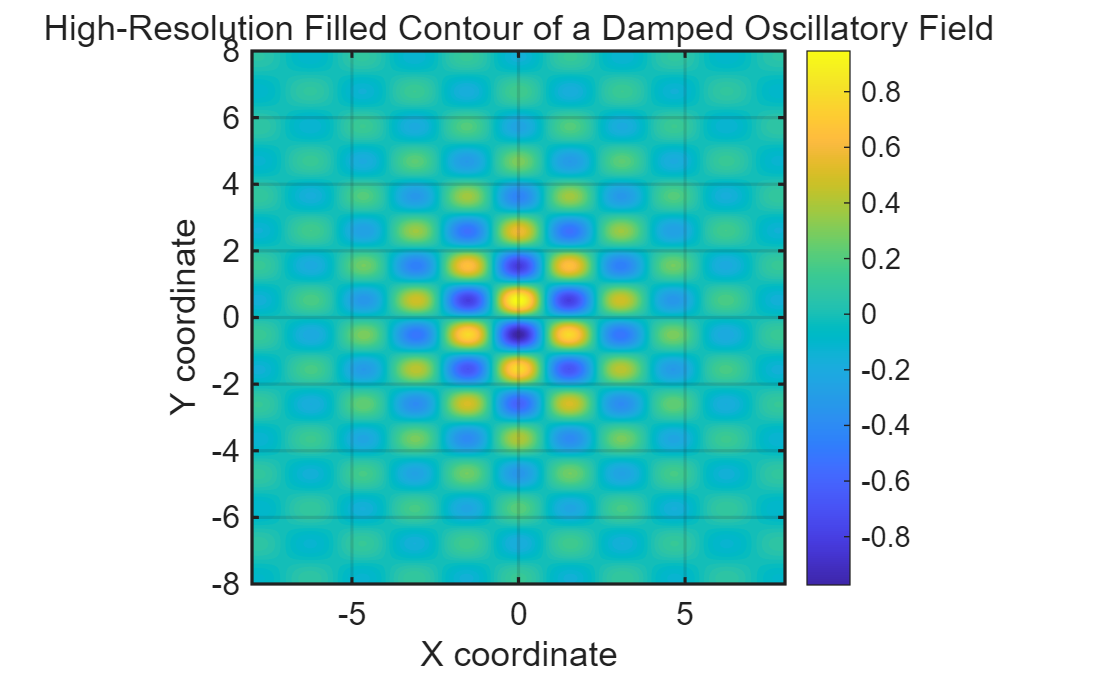

clear;
clc;

%a번 문제
x=linspace(-8,8,800);
y=linspace(-8,8,800);

%b번 문제
[X,Y]=meshgrid(x,y);

%c번 문제
Z=cos(2*X).*sin(3*Y)./(1+0.1*(X.^2+Y.^2));

%d번 문제
figure;
contourf(X,Y,Z,70,'LineColor','none');

%e번 문제
colormap(parula);
colorbar;
axis equal; 
grid on; 
box on;

%f번 문제
xlabel('X coordinate');
ylabel('Y coordinate');

%g번 문제
title('High-Resolution Filled Contour of a Damped Oscillatory Field');

%h번 문제
set(gca,'FontSize',12,'LineWidth',1.2);

14번 문제

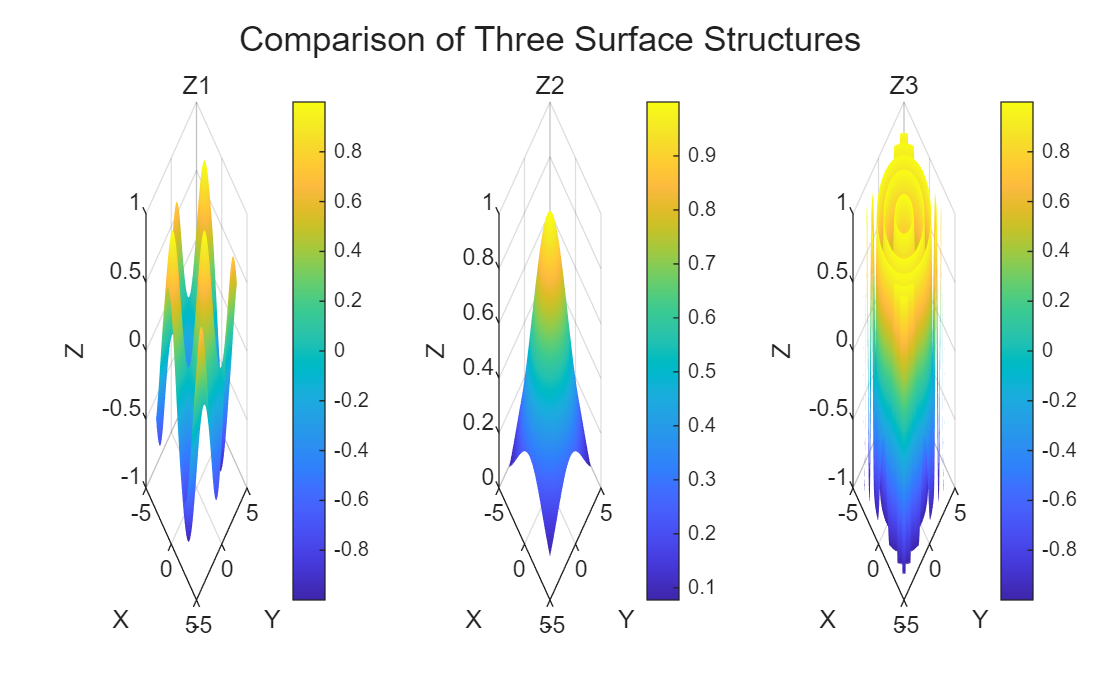

clear;
clc;

%a번 문제
x=linspace(-4,4,300);
y=linspace(-4,4,300);

%b번 문제
[X,Y]=meshgrid(x,y);

%c번 문제
Z1=sin(X).*cos(Y);
Z2=exp(-0.08*(X.^2+Y.^2));
Z3=sin(X.^2+Y.^2);

%d번 문제
figure;
tiledlayout(1,3);

%e번 문제 f번 문제 g번 문제
nexttile;
surf(X,Y,Z1);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z1');
view(45,30);

nexttile;
surf(X,Y,Z2);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z2');
view(45,30);

nexttile;
surf(X,Y,Z3);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z3');
view(45,30);

%h번 문제
sgtitle('Comparison of Three Surface Structures');

15번 문제

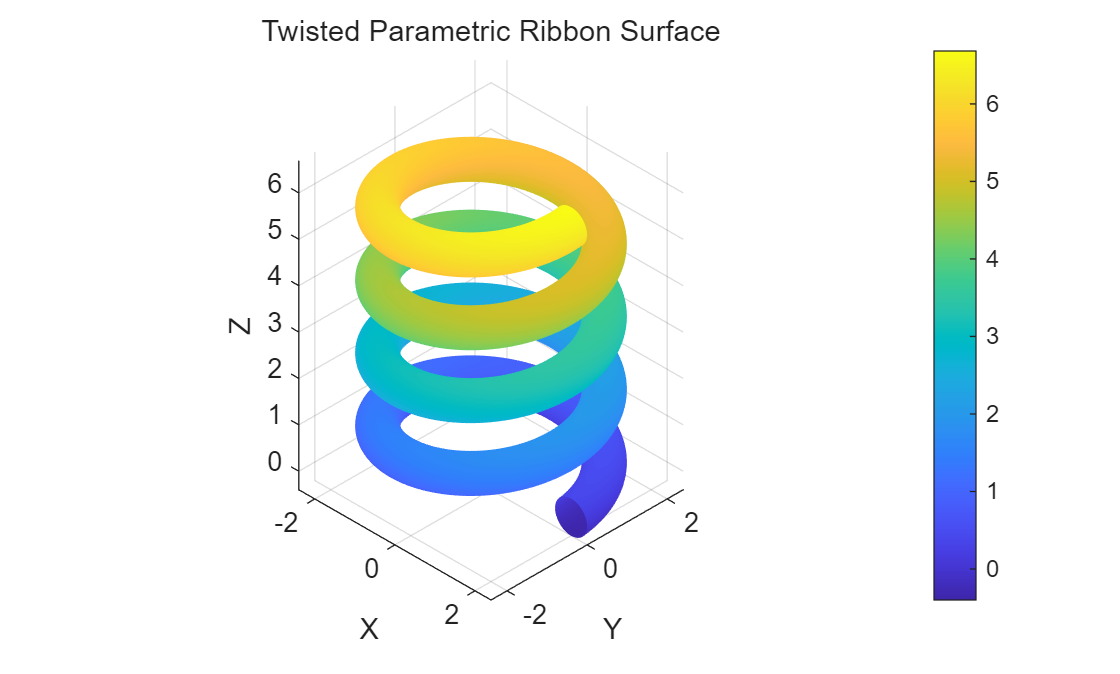

clear;
clc;

%a번 문제
u=linspace(0,8*pi,500);
v=linspace(-pi,pi,180);

%b번 문제
[U,V]=meshgrid(u,v);

%c번 문제
X=(2+0.4*cos(V)).*cos(U);
Y=(2+0.4*cos(V)).*sin(U);
Z=0.25*U+0.4*sin(V);

%d번 문제
figure;
surf(X,Y,Z);

%e번 문제
shading interp;
colormap(parula);
colorbar;

%f번 문제
xlabel('X');
ylabel('Y');
zlabel('Z');

%g번 문제
title('Twisted Parametric Ribbon Surface');

%h번 문제
axis equal;
axis tight;
grid on;
view(45,35);

%i번 문제
print('twisted_ribbon','-dpng','-r300');

16번 문제

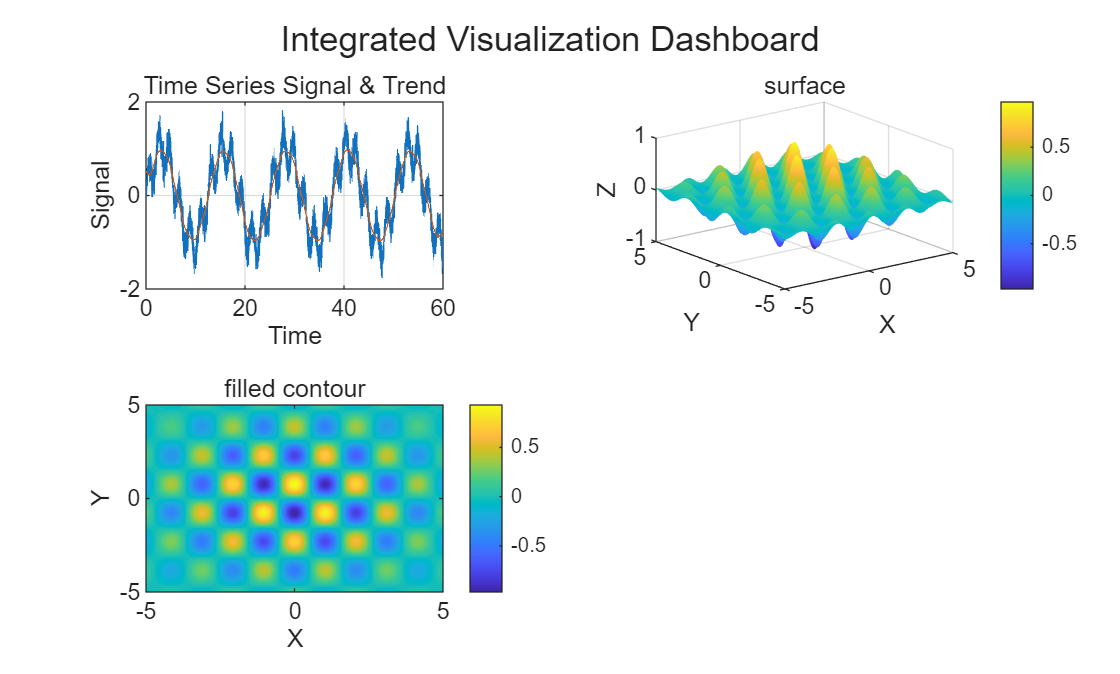

clear;
clc;

%a번 문제
rng(3);

%b번 문제
t=linspace(0,60,6000);
signal=sin(0.5*t)+0.4*sin(3*t)+0.15*randn(size(t));

%c번 문제
trend=movmean(signal,200);

%d번 문제
x=linspace(-5,5,300);
y=linspace(-5,5,300);
[X,Y]=meshgrid(x,y);

%e번 문제
Z=exp(-0.05*(X.^2+Y.^2)).*cos(3*X).*sin(2*Y);

%f번 문제
figure;
tiledlayout(2,2);

%g번 문제 %j번 문제
nexttile;
plot(t,signal);
hold on;
plot(t,trend);
title('Time Series Signal & Trend');
xlabel('Time');
ylabel('Signal');
hold off;
grid on;

%h번 문제 %j번 문제
nexttile;
surf(X,Y,Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('surface');
colorbar;
shading interp;
grid on;

%i번 문제 %j번 문제
nexttile;
contourf(X,Y,Z,50,'LineColor','none');
title('filled contour');
xlabel('X');
ylabel('Y');
colorbar;

nexttile;
axis off;

%k번 문제
sgtitle('Integrated Visualization Dashboard');

%l번 문제
print('visualization_dashboard','-dpng','-r300');